**Problem 1: Linear Regression**

% I) Exact Solution
% height (y) of an individual according to its age (x)
load('../data/data.mat')

% visualize data
figure(1)
plot(x, y, 'x'); 
xlabel('Age'); 
ylabel('Height');

**Find the linear regression parameters, W, in three different ways:**

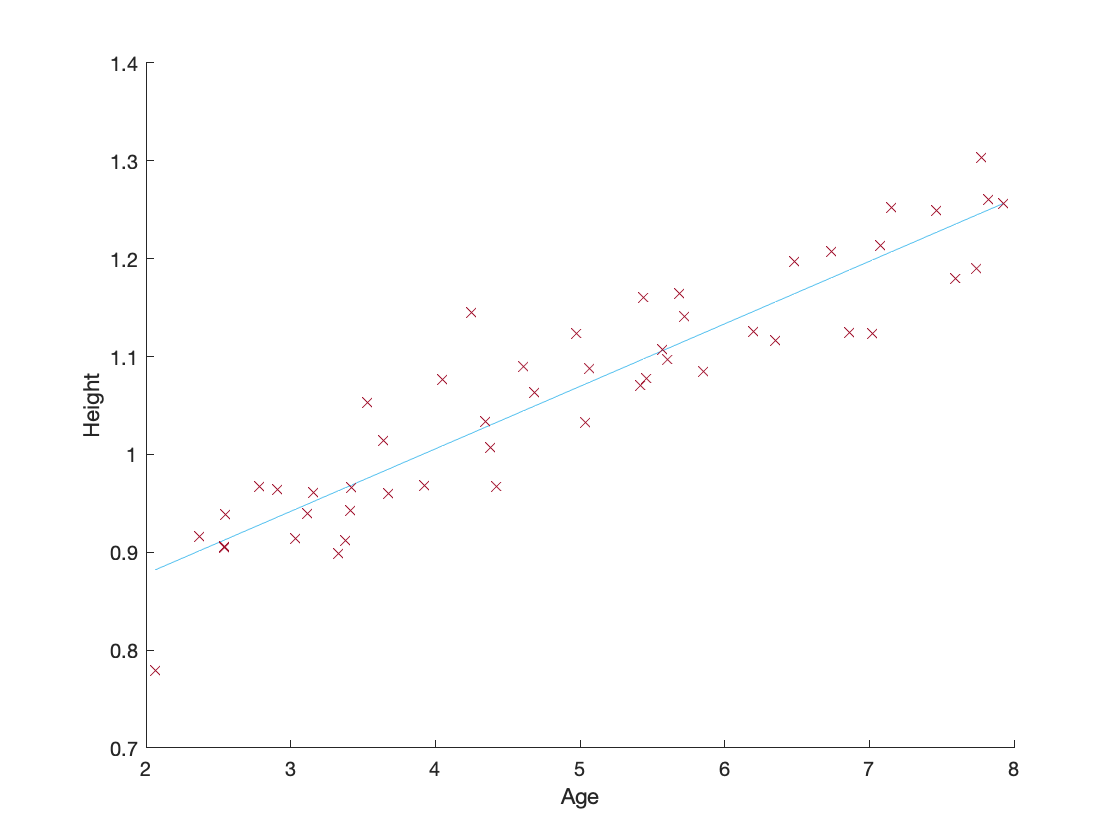

% a. Calculate the values of (𝑤-, 𝑤5) that minimize the least square error
A = [length(x), sum(x); ...
    sum(x), sum(x.^2) ];
B = [sum(y), sum(y.*x)].';

output = (A\B)';

w0 = output(1); 
w1 = output(2);
% dont use these: A = pinv(x)'*y'; y_hat = A'*x 

% b. Plot the curve corresponding to these parameters with the data as well
figure(2)
hold on;
plot(x, w0 + w1*x)
plot(x,y,'x')
xlabel('Age'); 
ylabel('Height');
hold off

% c. Predict the values of the height for both following persons aged of 3.5 and 7 years.
three_five = w0 + w1*3.5;
seven = w0 + w1*7;
disp(['3.5 y/o: ', num2str(three_five), newline,...
    '  7 y/o: ',num2str(seven)])

3.5 y/o: 0.97375
  7 y/o: 1.1973


% II) Gradient Descent Solution
N = length(x);
% W = zeros(1,length(x));
% W = 0;
% count = 1;

%     norm( (1/N) * (W'*x-y).*x ) > .001
while norm( (1/N) * sum( ((w0+w1*x)-y) .*x )) < .001
    % W = W - .07 * (1/N) * (W'*x-y).*x;
    W = W - .07 * (1/N) * sum( ((w0+w1*x)-y) .*x );
    count = count + 1;
end
disp(['W = ',num2str(W)])

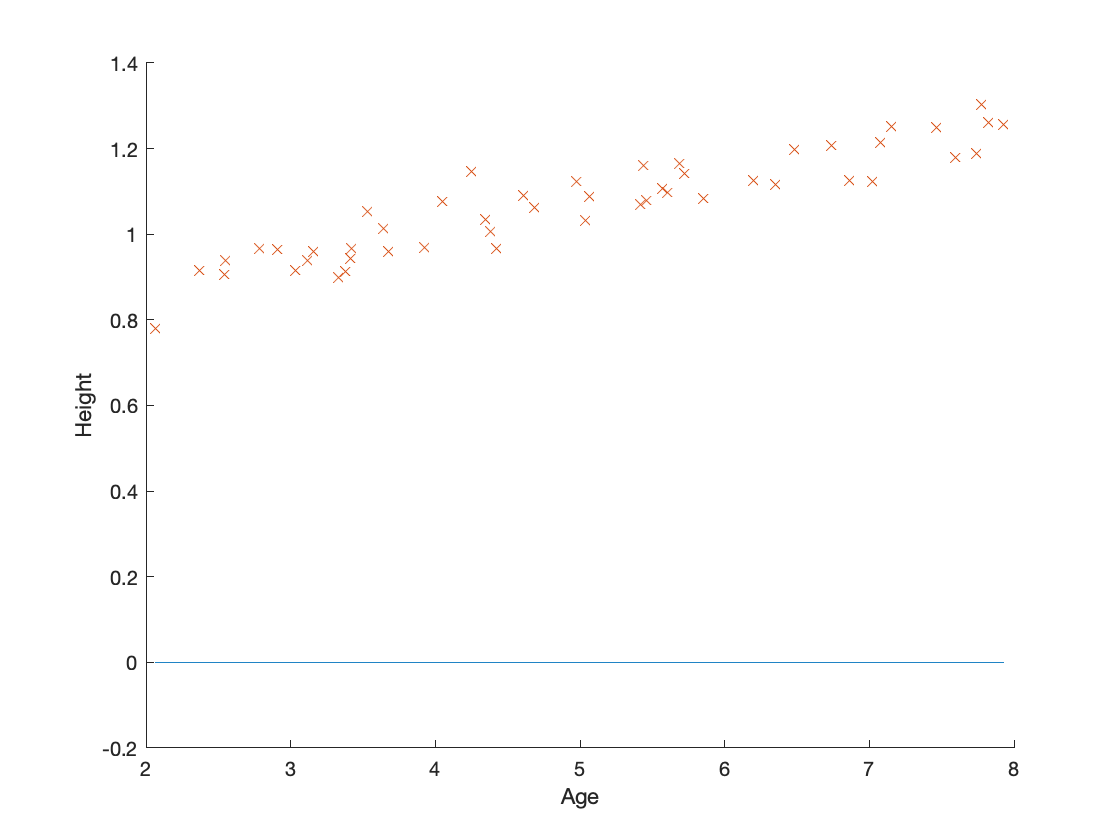

% Plot comparsison to Part 1
figure(3)
clf
hold on
plot(x, W'*x)
plot(x,y,'x')
xlabel('Age'); 
ylabel('Height');
hold off

No, did not obtain the same results as the exact solution. This output has a steeper slope and smaller y-intercept. 

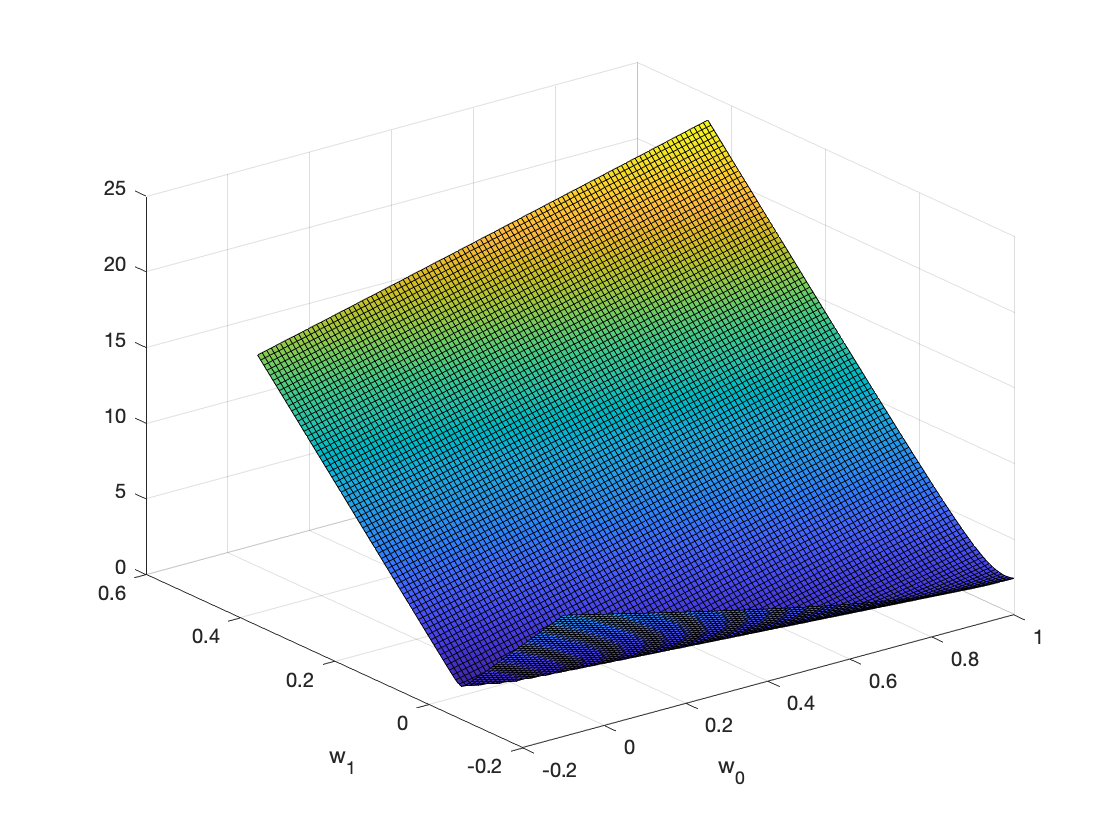

% Display the 3D curve of the error
error= zeros(100, 100);
W0 = linspace(-0.1, 1, 100); 
W1 = linspace(-0.2, 0.45, 100);
for i = 1:length(W0)
    for j = 1:length(W1)
        y_hat = W0(i)+W1(j)*x; 
        y_hat2 = W'*x;
        error(i,j) = norm(y_hat - y_hat2);
    end
end
error = error';
clf
figure(4)
surf(W0, W1, error) 
xlabel('w_0'); 
ylabel('w_1')
saveas(gcf, "../results/surfErorr.fig")

**3. What is the connection between this figure and the values found by the gradient descent algorithm? 	**

The depth in this figure (z-dimension) represents the distance (error) between the exact solution and the gradient descent solution.

Thus, the error in minimized at the lowest z-depth in the three-dimensional surface plot.

% III) Newton Optimization Solution
% 1. Implement Newton method starting from the origin of the search space W = 0. 
maximum = 25;
Wn = [0;0];
for i = 1:maximum
    for iter = 1:length(x)
        f1 = [(2*(Wn(1)+x(iter)*Wn(2) - y(iter)));(2*(Wn(1)+x(iter)*Wn(2) - y(iter)).*x(iter))];
        f2 = [2,2; 2*x(iter),2*x(iter).^2];
        Wn = Wn - (inv(f2) * f1);
    end
    
    summation = (1/N)*(sum(((X(iter,:)*Wn-y).*X(iter,:)),1));
    if norm(summation) <0.001
        break
    end
end

Unrecognized function or variable 'X'.


% predictions
pred_n1 = [1,3.5]*Wn;
pred_n2 = [1,7]*Wn;

figure;
plot(x, y,'x');
hold on
plot(x, Wn(1) + Wn(2)*x )